clear; clc;

main_dir        = 'D:/Research/MS_Thesis/Study2/Output';
IMG_DIR         = fullfile(main_dir, 'Image');
CLEANED_DIR     = fullfile(IMG_DIR, 'cleaned');
LSS_DIR         = fullfile(IMG_DIR, 'LSS', 'LSS_run01');
Quest_DATA      = fullfile(main_dir, 'Questionnaire', 'ques_data.csv');
NPS_DIR         = fullfile(IMG_DIR, 'NPS');
OUTPUT_DIR      = fullfile(IMG_DIR, 'MMM', 'mediation_run01');
group_mask      = 'D:/Research/MS_Thesis/Study2/Output/Image/masks/group_mask_belief_run01.nii';

cd('D:/Research/MS_Thesis/Study2/Analysis')
if exist(OUTPUT_DIR, 'dir')
    if strcmp(pwd, OUTPUT_DIR)
        cd(main_dir);
    end
    rmdir(OUTPUT_DIR, 's');
end
mkdir(OUTPUT_DIR);

TRIM_NII_DIR = fullfile(OUTPUT_DIR, 'trimmed_nii');
if ~exist(TRIM_NII_DIR, 'dir'), mkdir(TRIM_NII_DIR); end

quest_data     = readtable(Quest_DATA);
subid_num_vec  = double(string(quest_data.SubID));
formatted_keys = arrayfun(@(x) sprintf('%02d', x), subid_num_vec, 'UniformOutput', false);
group_num      = double(string(quest_data.Group) == "pain");
group_map      = containers.Map(formatted_keys, group_num);

tsv_files = dir(fullfile(CLEANED_DIR, 'sub-*_task-belief_run-01_events.tsv'));
n_subs    = numel(tsv_files);

X = cell(n_subs, 1);  Y = cell(n_subs, 1);  M = cell(n_subs, 1);
Group_vec = zeros(n_subs, 1);  NPS_vec = zeros(n_subs, 1);
subcount = 0;  skip_count = 0;

for i = 1:n_subs
    tsv_name     = tsv_files(i).name;
    subid        = regexp(tsv_name, 'sub-\d+', 'match', 'once');
    subid_padded = sprintf('%02d', str2double(regexp(tsv_name, '(?<=sub-)\d+', 'match', 'once')));

    nii_file = fullfile(LSS_DIR, sprintf('%s_task-belief_run-01_condition_feedback_lss.nii', subid));
    nps_file = fullfile(NPS_DIR, sprintf('sub-%s_task-belief_run-01_NPS.tsv', subid_padded));

    t          = readtable(fullfile(tsv_files(i).folder, tsv_name), 'FileType', 'text', 'Delimiter', '\t');
    t_feedback = t(strcmp(t.trial_type_mediation, 'feedback'), :);

    if isempty(t_feedback) || ~isfile(nii_file) || ~isfile(nps_file) || ~group_map.isKey(subid_padded)
        skip_count = skip_count + 1;
        continue;
    end

    EE_raw = double(t_feedback.EE);
    UP_raw = double(t_feedback.Update);

    EE_sub = EE_raw(1:end-1);
    UP_sub = UP_raw(1:end-1);

    nii_info = niftiinfo(nii_file);
    nii_data = niftiread(nii_info);

    nii_data_trim = nii_data(:, :, :, 1:end-1);

    if numel(EE_sub) ~= size(nii_data_trim, 4) || numel(UP_sub) ~= size(nii_data_trim, 4)
        warning('Mismatch %s: EE=%d, UP=%d, IMG=%d. Skipped.', ...
            subid, numel(EE_sub), numel(UP_sub), size(nii_data_trim,4));
        skip_count = skip_count + 1;
        continue;
    end

    trimmed_nii_file = fullfile(TRIM_NII_DIR, ...
        sprintf('%s_task-belief_run-01_condition_feedback_lss_trimlast.nii', subid));

    nii_info_trim = nii_info;
    nii_info_trim.ImageSize = size(nii_data_trim);
    niftiwrite(nii_data_trim, trimmed_nii_file, nii_info_trim, 'Compressed', false);


    EE_sub = EE_sub - mean(EE_sub, 'omitnan');
    UP_sub = UP_sub - mean(UP_sub, 'omitnan');

    nps_table = readtable(nps_file, 'FileType', 'text', 'Delimiter', '\t');

    subcount = subcount + 1;
    X{subcount}         = EE_sub;
    Y{subcount}         = UP_sub;
    M{subcount}         = trimmed_nii_file;
    Group_vec(subcount) = group_map(subid_padded);
    NPS_vec(subcount)   = mean(nps_table{:,1}, 'omitnan');
end

X = X(1:subcount);  Y = Y(1:subcount);  M = M(1:subcount);
Group_vec = Group_vec(1:subcount) * 2 - 1;
NPS_vec   = NPS_vec(1:subcount) - mean(NPS_vec(1:subcount));

fprintf('Included subjects: %d, Skipped: %d\n', subcount, skip_count);

Included subjects: 66, Skipped: 6


Search for mediators
First-level covariates:  None
Second-level moderators: None
Found mask: D:/Research/MS_Thesis/Study2/Output/Image/masks/group_mask_belief_run01.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
Preparing data.
Mask info:
Dimensions:  77  95  82
Voxels in mask: 251715
Mapping all input data volumes to memory
Subject   1,   1 images.
Subject   2,   1 images.
Subject   3,   1 images.
Subject   4,   1 images.
Subject   5,   1 images.
Subject   6,   1 images.
Subject   7,   1 images.
Subject   8,   1 images.
Subject   9,   1 images.
Subject  10,   1 images.
Subject  11,   1 images.
Subject  12,   1 images.
Subject  13,   1 images.
Subject  14,   1 images.
Subject  15,   1 images.
Subject  16,   1 images.
Subject  17,   1 images.
Subject  18,   1 images.
Subject  19,   1 images.
Subject  20,   1 images.
Subject  21,   1 images.
Subject  22,   1 images.
Subject  23,   1 images.
Subject  24,   1 images.
Subject

100% Elapsed:   7 s
Writing slice   4 in output images.
Slice   5, 180 in-mask voxels
Loading and preprocessing for this slice for subject: Summary of missing or bad voxels:
Dataset   1:  51 voxels have no data, and  51 voxels have missing data.
Dataset   2: 180 voxels have no data, and 180 voxels have missing data.
Dataset   3:  63 voxels have no data, and  63 voxels have missing data.
Dataset   4:  32 voxels have no data, and  32 voxels have missing data.
Dataset   5: 108 voxels have no data, and 108 voxels have missing data.
Dataset   6:  74 voxels have no data, and  74 voxels have missing data.
Dataset   7: 180 voxels have no data, and 180 voxels have missing data.
Dataset   8: 180 voxels have no data, and 180 voxels have missing data.
Dataset   9:  57 voxels have no data, and  57 voxels have missing data.
Dataset  10: 180 voxels have no data, and 180 voxels have missing data.
Dataset  11: 112 voxels have no data, and 112 voxels have missing data.
Dataset  12:  93 voxels have no da

 58%

 97%

 99%

100% Elapsed:   8 s
Writing slice   6 in output images.
Slice   7, 253 in-mask voxels
Loading and preprocessing for this slice for subject: Summary of missing or bad voxels:
Dataset   1: 119 voxels have no data, and 119 voxels have missing data.
Dataset   2: 253 voxels have no data, and 253 voxels have missing data.
Dataset   3: 122 voxels have no data, and 122 voxels have missing data.
Dataset   4:  73 voxels have no data, and  73 voxels have missing data.
Dataset   5:  58 voxels have no data, and  58 voxels have missing data.
Dataset   6: 156 voxels have no data, and 156 voxels have missing data.
Dataset   7: 253 voxels have no data, and 253 voxels have missing data.
Dataset   8: 249 voxels have no data, and 249 voxels have missing data.
Dataset   9: 118 voxels have no data, and 118 voxels have missing data.
Dataset  10: 253 voxels have no data, and 253 voxels have missing data.
Dataset  11:  98 voxels have no data, and  98 voxels have missing data.
Dataset  12: 134 voxels have no da

 25%

 31%

 38%

 45%

 58%

 70%

 90%

 94%

 96%

 98%

100% Elapsed:  10 s
Writing slice   7 in output images.
Slice   8, 471 in-mask voxels
Loading and preprocessing for this slice for subject: Summary of missing or bad voxels:
Dataset   1: 313 voxels have no data, and 313 voxels have missing data.
Dataset   2: 467 voxels have no data, and 467 voxels have missing data.
Dataset   3: 288 voxels have no data, and 288 voxels have missing data.
Dataset   4: 225 voxels have no data, and 225 voxels have missing data.
Dataset   5: 214 voxels have no data, and 214 voxels have missing data.
Dataset   6: 347 voxels have no data, and 347 voxels have missing data.
Dataset   7: 471 voxels have no data, and 471 voxels have missing data.
Dataset   8: 427 voxels have no data, and 427 voxels have missing data.
Dataset   9: 306 voxels have no data, and 306 voxels have missing data.
Dataset  10: 471 voxels have no data, and 471 voxels have missing data.
Dataset  11: 225 voxels have no data, and 225 voxels have missing data.
Dataset  12: 324 voxels have no da

  2%

  3%

  5%

 10%

 13%

 15%

 22%

 28%

 30%

 50%

 51%

 56%

 61%

 62%

 65%

 69%

 73%

 78%

 81%

 87%

 93%

 95%

 97%

 98%

 99%

100% Elapsed:  18 s
Writing slice   8 in output images.
Slice   9, 621 in-mask voxels
Loading and preprocessing for this slice for subject: Summary of missing or bad voxels:
Dataset   1: 363 voxels have no data, and 363 voxels have missing data.
Dataset   2: 483 voxels have no data, and 483 voxels have missing data.
Dataset   3: 274 voxels have no data, and 274 voxels have missing data.
Dataset   4: 237 voxels have no data, and 237 voxels have missing data.
Dataset   5: 210 voxels have no data, and 210 voxels have missing data.
Dataset   6: 389 voxels have no data, and 389 voxels have missing data.
Dataset   7: 621 voxels have no data, and 621 voxels have missing data.
Dataset   8: 441 voxels have no data, and 441 voxels have missing data.
Dataset   9: 350 voxels have no data, and 350 voxels have missing data.
Dataset  10: 621 voxels have no data, and 621 voxels have missing data.
Dataset  11: 175 voxels have no data, and 175 voxels have missing data.
Dataset  12: 375 voxels have no da

 17%

 61%

 66%

 70%

 71%

 74%

 78%

 81%

 82%

 83%

 84%

 86%

 95%

 97%

 98%

 99%

100%

 Elapsed:  24 s
Writing slice   9 in output images.
Slice  10, 755 in-mask voxels
Loading and preprocessing for this slice for subject: Summary of missing or bad voxels:
Dataset   1: 377 voxels have no data, and 377 voxels have missing data.
Dataset   2: 472 voxels have no data, and 472 voxels have missing data.
Dataset   3: 267 voxels have no data, and 267 voxels have missing data.
Dataset   4: 222 voxels have no data, and 222 voxels have missing data.
Dataset   5: 193 voxels have no data, and 193 voxels have missing data.
Dataset   6: 414 voxels have no data, and 414 voxels have missing data.
Dataset   7: 755 voxels have no data, and 755 voxels have missing data.
Dataset   8: 386 voxels have no data, and 386 voxels have missing data.
Dataset   9: 301 voxels have no data, and 301 voxels have missing data.
Dataset  10: 755 voxels have no data, and 755 voxels have missing data.
Dataset  11: 140 voxels have no data, and 140 voxels have missing data.
Dataset  12: 393 voxels have no data, 

  0%

 67%

 72%

 76%

 80%

 83%

 85%

 86%

 88%

 93%

 98%

 99%

100% Elapsed:  30 s
Writing slice  10 in output images.
Slice  11, 884 in-mask voxels
Loading and preprocessing for this slice for subject: Summary of missing or bad voxels:
Dataset   1: 358 voxels have no data, and 358 voxels have missing data.
Dataset   2: 458 voxels have no data, and 458 voxels have missing data.
Dataset   3: 272 voxels have no data, and 272 voxels have missing data.
Dataset   4: 199 voxels have no data, and 199 voxels have missing data.
Dataset   5: 185 voxels have no data, and 185 voxels have missing data.
Dataset   6: 444 voxels have no data, and 444 voxels have missing data.
Dataset   7: 884 voxels have no data, and 884 voxels have missing data.
Dataset   8: 365 voxels have no data, and 365 voxels have missing data.
Dataset   9: 309 voxels have no data, and 309 voxels have missing data.
Dataset  10: 884 voxels have no data, and 884 voxels have missing data.
Dataset  11: 141 voxels have no data, and 141 voxels have missing data.
Dataset  12: 436 voxels have no da

  1%

 12%

 63%

 77%

 81%

 84%

 89%

 91%

 92%

 97%

 98%

 99%

100%

 Elapsed:  34 s
Writing slice  11 in output images.
Slice  12, 990 in-mask voxels
Loading and preprocessing for this slice for subject: Summary of missing or bad voxels:
Dataset   1: 313 voxels have no data, and 313 voxels have missing data.
Dataset   2: 419 voxels have no data, and 419 voxels have missing data.
Dataset   3: 253 voxels have no data, and 253 voxels have missing data.
Dataset   4: 201 voxels have no data, and 201 voxels have missing data.
Dataset   5: 187 voxels have no data, and 187 voxels have missing data.
Dataset   6: 467 voxels have no data, and 467 voxels have missing data.
Dataset   7: 990 voxels have no data, and 990 voxels have missing data.
Dataset   8: 320 voxels have no data, and 320 voxels have missing data.
Dataset   9: 310 voxels have no data, and 310 voxels have missing data.
Dataset  10: 990 voxels have no data, and 990 voxels have missing data.
Dataset  11: 147 voxels have no data, and 147 voxels have missing data.
Dataset  12: 462 voxels have no data, 

  6%

  9%

 13%

 60%

 82%

 85%

 88%

 90%

 92%

 94%

 96%

 97%

 98%

 99%

100%

 Elapsed:  39 s
Writing slice  12 in output images.
Slice  13, 1098 in-mask voxels
Loading and preprocessing for this slice for subject: Summary of missing or bad voxels:
Dataset   1: 311 voxels have no data, and 311 voxels have missing data.
Dataset   2: 413 voxels have no data, and 413 voxels have missing data.
Dataset   3: 257 voxels have no data, and 257 voxels have missing data.
Dataset   4: 211 voxels have no data, and 211 voxels have missing data.
Dataset   5: 213 voxels have no data, and 213 voxels have missing data.
Dataset   6: 488 voxels have no data, and 488 voxels have missing data.
Dataset   7: 1098 voxels have no data, and 1098 voxels have missing data.
Dataset   8: 318 voxels have no data, and 318 voxels have missing data.
Dataset   9: 323 voxels have no data, and 323 voxels have missing data.
Dataset  10: 1098 voxels have no data, and 1098 voxels have missing data.
Dataset  11: 166 voxels have no data, and 166 voxels have missing data.
Dataset  12: 494 voxels have no d

  9%

 13%

 17%

 61%

 90%

 92%

 94%

 95%

 96%

 97%

 98%

 99%

100%

 Elapsed:  43 s
Writing slice  13 in output images.
Slice  14, 1329 in-mask voxels
Loading and preprocessing for this slice for subject: Summary of missing or bad voxels:
Dataset   1: 428 voxels have no data, and 428 voxels have missing data.
Dataset   2: 530 voxels have no data, and 530 voxels have missing data.
Dataset   3: 317 voxels have no data, and 317 voxels have missing data.
Dataset   4: 261 voxels have no data, and 261 voxels have missing data.
Dataset   5: 348 voxels have no data, and 348 voxels have missing data.
Dataset   6: 647 voxels have no data, and 647 voxels have missing data.
Dataset   7: 1329 voxels have no data, and 1329 voxels have missing data.
Dataset   8: 458 voxels have no data, and 458 voxels have missing data.
Dataset   9: 459 voxels have no data, and 459 voxels have missing data.
Dataset  10: 1329 voxels have no data, and 1329 voxels have missing data.
Dataset  11: 322 voxels have no data, and 322 voxels have missing data.
Dataset  12: 598 voxels have no d

  4%

 71%

 78%

 80%

 82%

 83%

 84%

 85%

 86%

 87%

 88%

 89%

 91%

 93%

 97%

 98%

 99%

100%

 Elapsed:  51 s
Writing slice  14 in output images.
Slice  15, 1571 in-mask voxels
Loading and preprocessing for this slice for subject: Summary of missing or bad voxels:
Dataset   1: 525 voxels have no data, and 525 voxels have missing data.
Dataset   2: 576 voxels have no data, and 576 voxels have missing data.
Dataset   3: 389 voxels have no data, and 389 voxels have missing data.
Dataset   4: 290 voxels have no data, and 290 voxels have missing data.
Dataset   5: 397 voxels have no data, and 397 voxels have missing data.
Dataset   6: 794 voxels have no data, and 794 voxels have missing data.
Dataset   7: 1571 voxels have no data, and 1571 voxels have missing data.
Dataset   8: 587 voxels have no data, and 587 voxels have missing data.
Dataset   9: 594 voxels have no data, and 594 voxels have missing data.
Dataset  10: 1571 voxels have no data, and 1571 voxels have missing data.
Dataset  11: 453 voxels have no data, and 453 voxels have missing data.
Dataset  12: 709 voxels have no d

  8%

 74%

 76%

 77%

 78%

 79%

 80%

 81%

 82%

 83%

 84%

 86%

 88%

 91%

 92%

 93%

 94%

 95%

 96%

 97%

 98%

 99%

100% Elapsed:  60 s
Writing slice  15 in output images.
Slice  16, 1769 in-mask voxels
Loading and preprocessing for this slice for subject: Summary of missing or bad voxels:
Dataset   1: 582 voxels have no data, and 582 voxels have missing data.
Dataset   2: 553 voxels have no data, and 553 voxels have missing data.
Dataset   3: 426 voxels have no data, and 426 voxels have missing data.
Dataset   4: 295 voxels have no data, and 295 voxels have missing data.
Dataset   5: 398 voxels have no data, and 398 voxels have missing data.
Dataset   6: 899 voxels have no data, and 899 voxels have missing data.
Dataset   7: 1769 voxels have no data, and 1769 voxels have missing data.
Dataset   8: 620 voxels have no data, and 620 voxels have missing data.
Dataset   9: 664 voxels have no data, and 664 voxels have missing data.
Dataset  10: 1769 voxels have no data, and 1769 voxels have missing data.
Dataset  11: 487 voxels have no data, and 487 voxels have missing data.
Dataset  12: 722 voxels have 

 71%

 72%

 73%

 74%

 76%

 77%

 78%

 80%

 81%

 82%

 83%

 84%

 87%

 90%

 92%

 94%

 95%

 96%

 97%

 98%

 99%

100% Elapsed:  67 s
Writing slice  16 in output images.
Slice  17, 1945 in-mask voxels
Loading and preprocessing for this slice for subject: Summary of missing or bad voxels:
Dataset   1: 652 voxels have no data, and 652 voxels have missing data.
Dataset   2: 533 voxels have no data, and 533 voxels have missing data.
Dataset   3: 438 voxels have no data, and 438 voxels have missing data.
Dataset   4: 322 voxels have no data, and 322 voxels have missing data.
Dataset   5: 410 voxels have no data, and 410 voxels have missing data.
Dataset   6: 929 voxels have no data, and 929 voxels have missing data.
Dataset   7: 1945 voxels have no data, and 1945 voxels have missing data.
Dataset   8: 654 voxels have no data, and 654 voxels have missing data.
Dataset   9: 683 voxels have no data, and 683 voxels have missing data.
Dataset  10: 1945 voxels have no data, and 1945 voxels have missing data.
Dataset  11: 441 voxels have no data, and 441 voxels have missing data.
Dataset  12: 715 voxels have 

 69%

 71%

 73%

 74%

 75%

 75%

 76%

 78%

 79%

 83%

 86%

 88%

 89%

 91%

 92%

 93%

 94%

 95%

 96%

 97%

 99%

100%

 Elapsed:  76 s
Writing slice  17 in output images.
Slice  18, 2091 in-mask voxels
Loading and preprocessing for this slice for subject: Summary of missing or bad voxels:
Dataset   1: 697 voxels have no data, and 697 voxels have missing data.
Dataset   2: 545 voxels have no data, and 545 voxels have missing data.
Dataset   3: 482 voxels have no data, and 482 voxels have missing data.
Dataset   4: 334 voxels have no data, and 334 voxels have missing data.
Dataset   5: 439 voxels have no data, and 439 voxels have missing data.
Dataset   6: 952 voxels have no data, and 952 voxels have missing data.
Dataset   7: 2090 voxels have no data, and 2090 voxels have missing data.
Dataset   8: 698 voxels have no data, and 698 voxels have missing data.
Dataset   9: 634 voxels have no data, and 634 voxels have missing data.
Dataset  10: 2091 voxels have no data, and 2091 voxels have missing data.
Dataset  11: 406 voxels have no data, and 406 voxels have missing data.
Dataset  12: 746 voxels have no d

 14%

 66%

 68%

 69%

 71%

 72%

 73%

 74%

 75%

 77%

 80%

 82%

 85%

 87%

 88%

 90%

 91%

 93%

 97%

 98%

 99%

100%

 Elapsed:  80 s
Writing slice  18 in output images.
Slice  19, 2227 in-mask voxels
Loading and preprocessing for this slice for subject: Summary of missing or bad voxels:
Dataset   1: 757 voxels have no data, and 757 voxels have missing data.
Dataset   2: 586 voxels have no data, and 586 voxels have missing data.
Dataset   3: 519 voxels have no data, and 519 voxels have missing data.
Dataset   4: 334 voxels have no data, and 334 voxels have missing data.
Dataset   5: 457 voxels have no data, and 457 voxels have missing data.
Dataset   6: 949 voxels have no data, and 949 voxels have missing data.
Dataset   7: 2222 voxels have no data, and 2222 voxels have missing data.
Dataset   8: 729 voxels have no data, and 729 voxels have missing data.
Dataset   9: 608 voxels have no data, and 608 voxels have missing data.
Dataset  10: 2227 voxels have no data, and 2227 voxels have missing data.
Dataset  11: 395 voxels have no data, and 395 voxels have missing data.
Dataset  12: 813 voxels have no d

 10%

 59%

 63%

 65%

 66%

 67%

 68%

 69%

 70%

 71%

 72%

 73%

 78%

 80%

 83%

 84%

 85%

 86%

 87%

 88%

 90%

 92%

 94%

 95%

 96%

 97%

 98%

 99%

100%

 Elapsed:  87 s
Writing slice  19 in output images.
Slice  20, 2368 in-mask voxels
Loading and preprocessing for this slice for subject: Summary of missing or bad voxels:
Dataset   1: 835 voxels have no data, and 835 voxels have missing data.
Dataset   2: 651 voxels have no data, and 651 voxels have missing data.
Dataset   3: 557 voxels have no data, and 557 voxels have missing data.
Dataset   4: 363 voxels have no data, and 363 voxels have missing data.
Dataset   5: 496 voxels have no data, and 496 voxels have missing data.
Dataset   6: 969 voxels have no data, and 969 voxels have missing data.
Dataset   7: 2355 voxels have no data, and 2355 voxels have missing data.
Dataset   8: 790 voxels have no data, and 790 voxels have missing data.
Dataset   9: 636 voxels have no data, and 636 voxels have missing data.
Dataset  10: 2368 voxels have no data, and 2368 voxels have missing data.
Dataset  11: 402 voxels have no data, and 402 voxels have missing data.
Dataset  12: 901 voxels have no d

 59%

 61%

 62%

 63%

 64%

 65%

 66%

 67%

 68%

 69%

 70%

 71%

 72%

 74%

 76%

 80%

 84%

 87%

 89%

 92%

 93%

 94%

 95%

 96%

 97%

 98%

 99%

100% Elapsed:  93 s
Writing slice  20 in output images.
Slice  21, 2500 in-mask voxels
Loading and preprocessing for this slice for subject: Summary of missing or bad voxels:
Dataset   1: 864 voxels have no data, and 864 voxels have missing data.
Dataset   2: 682 voxels have no data, and 682 voxels have missing data.
Dataset   3: 580 voxels have no data, and 580 voxels have missing data.
Dataset   4: 390 voxels have no data, and 390 voxels have missing data.
Dataset   5: 522 voxels have no data, and 522 voxels have missing data.
Dataset   6: 967 voxels have no data, and 967 voxels have missing data.
Dataset   7: 2482 voxels have no data, and 2482 voxels have missing data.
Dataset   8: 869 voxels have no data, and 869 voxels have missing data.
Dataset   9: 683 voxels have no data, and 683 voxels have missing data.
Dataset  10: 2500 voxels have no data, and 2500 voxels have missing data.
Dataset  11: 423 voxels have no data, and 423 voxels have missing data.
Dataset  12: 999 voxels have 

 57%

 58%

 60%

 61%

 63%

 64%

 65%

 66%

 67%

 69%

 70%

 72%

 74%

 75%

 80%

 82%

 85%

 93%

100% Elapsed:  98 s
Writing slice  21 in output images.
Slice  22, 2593 in-mask voxels
Loading and preprocessing for this slice for subject: Summary of missing or bad voxels:
Dataset   1: 840 voxels have no data, and 840 voxels have missing data.
Dataset   2: 668 voxels have no data, and 668 voxels have missing data.
Dataset   3: 566 voxels have no data, and 566 voxels have missing data.
Dataset   4: 371 voxels have no data, and 371 voxels have missing data.
Dataset   5: 529 voxels have no data, and 529 voxels have missing data.
Dataset   6: 939 voxels have no data, and 939 voxels have missing data.
Dataset   7: 2567 voxels have no data, and 2567 voxels have missing data.
Dataset   8: 879 voxels have no data, and 879 voxels have missing data.
Dataset   9: 696 voxels have no data, and 696 voxels have missing data.
Dataset  10: 2593 voxels have no data, and 2593 voxels have missing data.
Dataset  11: 445 voxels have no data, and 445 voxels have missing data.
Dataset  12: 1011 voxels have

 52%

 57%

 58%

 59%

 61%

 62%

 63%

 64%

 65%

 66%

 67%

 68%

 69%

 70%

 73%

 74%

 75%

 78%

 80%

 84%

 92%

 94%

 96%

100% Elapsed: 102 s
Writing slice  22 in output images.
Slice  23, 2689 in-mask voxels
Loading and preprocessing for this slice for subject: Summary of missing or bad voxels:
Dataset   1: 849 voxels have no data, and 849 voxels have missing data.
Dataset   2: 699 voxels have no data, and 699 voxels have missing data.
Dataset   3: 560 voxels have no data, and 560 voxels have missing data.
Dataset   4: 375 voxels have no data, and 375 voxels have missing data.
Dataset   5: 546 voxels have no data, and 546 voxels have missing data.
Dataset   6: 923 voxels have no data, and 923 voxels have missing data.
Dataset   7: 2650 voxels have no data, and 2650 voxels have missing data.
Dataset   8: 932 voxels have no data, and 932 voxels have missing data.
Dataset   9: 736 voxels have no data, and 736 voxels have missing data.
Dataset  10: 2689 voxels have no data, and 2689 voxels have missing data.
Dataset  11: 479 voxels have no data, and 479 voxels have missing data.
Dataset  12: 1024 voxels have

 51%

 54%

 55%

 58%

 61%

 62%

 64%

 65%

 66%

 67%

 69%

 71%

 74%

 76%

 78%

 79%

 81%

 83%

 84%

 86%

 88%

 89%

 91%

 92%

 93%

 95%

 96%

 98%

 99%

100%

 Elapsed: 107 s
Writing slice  23 in output images.
Slice  24, 2830 in-mask voxels
Loading and preprocessing for this slice for subject: Summary of missing or bad voxels:
Dataset   1: 920 voxels have no data, and 920 voxels have missing data.
Dataset   2: 776 voxels have no data, and 776 voxels have missing data.
Dataset   3: 563 voxels have no data, and 563 voxels have missing data.
Dataset   4: 419 voxels have no data, and 419 voxels have missing data.
Dataset   5: 572 voxels have no data, and 572 voxels have missing data.
Dataset   6: 870 voxels have no data, and 870 voxels have missing data.
Dataset   7: 2771 voxels have no data, and 2771 voxels have missing data.
Dataset   8: 1034 voxels have no data, and 1034 voxels have missing data.
Dataset   9: 858 voxels have no data, and 858 voxels have missing data.
Dataset  10: 2830 voxels have no data, and 2830 voxels have missing data.
Dataset  11: 505 voxels have no data, and 505 voxels have missing data.
Dataset  12: 990 voxels have no

  0%

  1%

 53%

 54%

 56%

 59%

 60%

 62%

 63%

 64%

 65%

 66%

 68%

 69%

 70%

 71%

 73%

 75%

 78%

 79%

 85%

 87%

 88%

 90%

 91%

 93%

 94%

 97%

100% Elapsed: 112 s
Writing slice  24 in output images.
Slice  25, 3068 in-mask voxels
Loading and preprocessing for this slice for subject: Summary of missing or bad voxels:
Dataset   1: 1055 voxels have no data, and 1055 voxels have missing data.
Dataset   2: 910 voxels have no data, and 910 voxels have missing data.
Dataset   3: 620 voxels have no data, and 620 voxels have missing data.
Dataset   4: 552 voxels have no data, and 552 voxels have missing data.
Dataset   5: 690 voxels have no data, and 690 voxels have missing data.
Dataset   6: 812 voxels have no data, and 812 voxels have missing data.
Dataset   7: 2970 voxels have no data, and 2970 voxels have missing data.
Dataset   8: 1203 voxels have no data, and 1203 voxels have missing data.
Dataset   9: 991 voxels have no data, and 991 voxels have missing data.
Dataset  10: 3068 voxels have no data, and 3068 voxels have missing data.
Dataset  11: 576 voxels have no data, and 576 voxels have missing data.
Dataset  12: 960 voxels h

  1%

 57%

 58%

 60%

 62%

 64%

 66%

 68%

 70%

 72%

 74%

 77%

 81%

 83%

 85%

 87%

 89%

 91%

 92%

 93%

 94%

 95%

 97%

 98%

 99%

100%

 Elapsed: 120 s
Writing slice  25 in output images.
Slice  26, 3260 in-mask voxels
Loading and preprocessing for this slice for subject: Summary of missing or bad voxels:
Dataset   1: 995 voxels have no data, and 995 voxels have missing data.
Dataset   2: 934 voxels have no data, and 934 voxels have missing data.
Dataset   3: 628 voxels have no data, and 628 voxels have missing data.
Dataset   4: 624 voxels have no data, and 624 voxels have missing data.
Dataset   5: 707 voxels have no data, and 707 voxels have missing data.
Dataset   6: 689 voxels have no data, and 689 voxels have missing data.
Dataset   7: 3127 voxels have no data, and 3127 voxels have missing data.
Dataset   8: 1229 voxels have no data, and 1229 voxels have missing data.
Dataset   9: 986 voxels have no data, and 986 voxels have missing data.
Dataset  10: 3260 voxels have no data, and 3260 voxels have missing data.
Dataset  11: 591 voxels have no data, and 591 voxels have missing data.
Dataset  12: 903 voxels have no

 58%

 73%

 74%

 76%

 77%

 78%

 80%

 82%

 84%

 85%

 86%

 87%

 88%

 89%

 91%

 92%

 93%

 94%

 95%

 96%

 97%

 98%

 99%

100%

 Elapsed: 128 s
Writing slice  26 in output images.
Slice  27, 3457 in-mask voxels
Loading and preprocessing for this slice for subject: Summary of missing or bad voxels:
Dataset   1: 967 voxels have no data, and 967 voxels have missing data.
Dataset   2: 912 voxels have no data, and 912 voxels have missing data.
Dataset   3: 629 voxels have no data, and 629 voxels have missing data.
Dataset   4: 703 voxels have no data, and 703 voxels have missing data.
Dataset   5: 701 voxels have no data, and 701 voxels have missing data.
Dataset   6: 666 voxels have no data, and 666 voxels have missing data.
Dataset   7: 3294 voxels have no data, and 3294 voxels have missing data.
Dataset   8: 1204 voxels have no data, and 1204 voxels have missing data.
Dataset   9: 1000 voxels have no data, and 1000 voxels have missing data.
Dataset  10: 3453 voxels have no data, and 3453 voxels have missing data.
Dataset  11: 555 voxels have no data, and 555 voxels have missing data.
Dataset  12: 802 voxels have 

  2%

 82%

 83%

 85%

 88%

 90%

 91%

 93%

 94%

 95%

 96%

 97%

 99%

100%

 Elapsed: 137 s
Writing slice  27 in output images.
Slice  28, 3693 in-mask voxels
Loading and preprocessing for this slice for subject: Summary of missing or bad voxels:
Dataset   1: 1001 voxels have no data, and 1001 voxels have missing data.
Dataset   2: 932 voxels have no data, and 932 voxels have missing data.
Dataset   3: 633 voxels have no data, and 633 voxels have missing data.
Dataset   4: 772 voxels have no data, and 772 voxels have missing data.
Dataset   5: 640 voxels have no data, and 640 voxels have missing data.
Dataset   6: 623 voxels have no data, and 623 voxels have missing data.
Dataset   7: 3497 voxels have no data, and 3497 voxels have missing data.
Dataset   8: 1127 voxels have no data, and 1127 voxels have missing data.
Dataset   9: 1038 voxels have no data, and 1038 voxels have missing data.
Dataset  10: 3664 voxels have no data, and 3664 voxels have missing data.
Dataset  11: 494 voxels have no data, and 494 voxels have missing data.
Dataset  12: 651 voxels hav

  2%

  6%

 87%

 88%

 89%

 90%

 91%

 92%

 93%

 95%

 97%

 99%

100%

 Elapsed: 149 s
Writing slice  28 in output images.
Slice  29, 4117 in-mask voxels
Loading and preprocessing for this slice for subject: Summary of missing or bad voxels:
Dataset   1: 1163 voxels have no data, and 1163 voxels have missing data.
Dataset   2: 1071 voxels have no data, and 1071 voxels have missing data.
Dataset   3: 793 voxels have no data, and 793 voxels have missing data.
Dataset   4: 983 voxels have no data, and 983 voxels have missing data.
Dataset   5: 680 voxels have no data, and 680 voxels have missing data.
Dataset   6: 718 voxels have no data, and 718 voxels have missing data.
Dataset   7: 3850 voxels have no data, and 3850 voxels have missing data.
Dataset   8: 1128 voxels have no data, and 1128 voxels have missing data.
Dataset   9: 1207 voxels have no data, and 1207 voxels have missing data.
Dataset  10: 4010 voxels have no data, and 4010 voxels have missing data.
Dataset  11: 490 voxels have no data, and 490 voxels have missing data.
Dataset  12: 609 voxels h

  2%

  3%

  5%

 11%

 84%

 85%

 96%

100% Elapsed: 169 s
Writing slice  29 in output images.
Slice  30, 4486 in-mask voxels
Loading and preprocessing for this slice for subject: Summary of missing or bad voxels:
Dataset   1: 1116 voxels have no data, and 1116 voxels have missing data.
Dataset   2: 1037 voxels have no data, and 1037 voxels have missing data.
Dataset   3: 774 voxels have no data, and 774 voxels have missing data.
Dataset   4: 984 voxels have no data, and 984 voxels have missing data.
Dataset   5: 567 voxels have no data, and 567 voxels have missing data.
Dataset   6: 723 voxels have no data, and 723 voxels have missing data.
Dataset   7: 4039 voxels have no data, and 4039 voxels have missing data.
Dataset   8: 1041 voxels have no data, and 1041 voxels have missing data.
Dataset   9: 1267 voxels have no data, and 1267 voxels have missing data.
Dataset  10: 4252 voxels have no data, and 4252 voxels have missing data.
Dataset  11: 416 voxels have no data, and 416 voxels have missing data.
Dataset  12: 565 voxe

 83%

 84%

100% Elapsed: 186 s
Writing slice  30 in output images.
Slice  31, 4749 in-mask voxels
Loading and preprocessing for this slice for subject: Summary of missing or bad voxels:
Dataset   1: 1051 voxels have no data, and 1051 voxels have missing data.
Dataset   2: 976 voxels have no data, and 976 voxels have missing data.
Dataset   3: 711 voxels have no data, and 711 voxels have missing data.
Dataset   4: 881 voxels have no data, and 881 voxels have missing data.
Dataset   5: 411 voxels have no data, and 411 voxels have missing data.
Dataset   6: 555 voxels have no data, and 555 voxels have missing data.
Dataset   7: 4077 voxels have no data, and 4077 voxels have missing data.
Dataset   8: 955 voxels have no data, and 955 voxels have missing data.
Dataset   9: 1098 voxels have no data, and 1098 voxels have missing data.
Dataset  10: 4396 voxels have no data, and 4396 voxels have missing data.
Dataset  11: 351 voxels have no data, and 351 voxels have missing data.
Dataset  12: 486 voxels h

100% Elapsed: 205 s
Writing slice  32 in output images.
Slice  33, 5038 in-mask voxels
Loading and preprocessing for this slice for subject: Summary of missing or bad voxels:
Dataset   1: 687 voxels have no data, and 687 voxels have missing data.
Dataset   2: 763 voxels have no data, and 763 voxels have missing data.
Dataset   3: 475 voxels have no data, and 475 voxels have missing data.
Dataset   4: 536 voxels have no data, and 536 voxels have missing data.
Dataset   5: 261 voxels have no data, and 261 voxels have missing data.
Dataset   6: 253 voxels have no data, and 253 voxels have missing data.
Dataset   7: 3878 voxels have no data, and 3878 voxels have missing data.
Dataset   8: 811 voxels have no data, and 811 voxels have missing data.
Dataset   9: 746 voxels have no data, and 746 voxels have missing data.
Dataset  10: 4341 voxels have no data, and 4341 voxels have missing data.
Dataset  11: 247 voxels have no data, and 247 voxels have missing data.
Dataset  12: 512 voxels have 

100% Elapsed: 230 s
Writing slice  37 in output images.
Slice  38, 5325 in-mask voxels
Loading and preprocessing for this slice for subject: Summary of missing or bad voxels:
Dataset   1: 291 voxels have no data, and 291 voxels have missing data.
Dataset   2: 548 voxels have no data, and 548 voxels have missing data.
Dataset   3: 217 voxels have no data, and 217 voxels have missing data.
Dataset   4: 136 voxels have no data, and 136 voxels have missing data.
Dataset   5: 252 voxels have no data, and 252 voxels have missing data.
Dataset   6: 194 voxels have no data, and 194 voxels have missing data.
Dataset   7: 3688 voxels have no data, and 3688 voxels have missing data.
Dataset   8: 722 voxels have no data, and 722 voxels have missing data.
Dataset   9: 387 voxels have no data, and 387 voxels have missing data.
Dataset  10: 3853 voxels have no data, and 3853 voxels have missing data.
Dataset  11: 196 voxels have no data, and 196 voxels have missing data.
Dataset  12: 628 voxels have 

100% Elapsed: 232 s
Writing slice  44 in output images.
Slice  45, 5305 in-mask voxels
Loading and preprocessing for this slice for subject: Summary of missing or bad voxels:
Dataset   1: 218 voxels have no data, and 218 voxels have missing data.
Dataset   2: 346 voxels have no data, and 346 voxels have missing data.
Dataset   3:  67 voxels have no data, and  67 voxels have missing data.
Dataset   4: 144 voxels have no data, and 144 voxels have missing data.
Dataset   5: 162 voxels have no data, and 162 voxels have missing data.
Dataset   6: 183 voxels have no data, and 183 voxels have missing data.
Dataset   7: 2854 voxels have no data, and 2854 voxels have missing data.
Dataset   8: 356 voxels have no data, and 356 voxels have missing data.
Dataset   9: 268 voxels have no data, and 268 voxels have missing data.
Dataset  10: 3340 voxels have no data, and 3340 voxels have missing data.
Dataset  11: 155 voxels have no data, and 155 voxels have missing data.
Dataset  12: 326 voxels have 

100% Elapsed: 225 s
Writing slice  47 in output images.
Slice  48, 5173 in-mask voxels
Loading and preprocessing for this slice for subject: Summary of missing or bad voxels:
Dataset   1: 180 voxels have no data, and 180 voxels have missing data.
Dataset   2: 306 voxels have no data, and 306 voxels have missing data.
Dataset   3:  37 voxels have no data, and  37 voxels have missing data.
Dataset   4:  89 voxels have no data, and  89 voxels have missing data.
Dataset   5: 137 voxels have no data, and 137 voxels have missing data.
Dataset   6: 182 voxels have no data, and 182 voxels have missing data.
Dataset   7: 2635 voxels have no data, and 2635 voxels have missing data.
Dataset   8: 217 voxels have no data, and 217 voxels have missing data.
Dataset   9: 240 voxels have no data, and 240 voxels have missing data.
Dataset  10: 3076 voxels have no data, and 3076 voxels have missing data.
Dataset  11: 136 voxels have no data, and 136 voxels have missing data.
Dataset  12: 304 voxels have 

100% Elapsed: 220 s
Writing slice  49 in output images.
Slice  50, 5076 in-mask voxels
Loading and preprocessing for this slice for subject: Summary of missing or bad voxels:
Dataset   1: 198 voxels have no data, and 198 voxels have missing data.
Dataset   2: 273 voxels have no data, and 273 voxels have missing data.
Dataset   3:  20 voxels have no data, and  20 voxels have missing data.
Dataset   4:  58 voxels have no data, and  58 voxels have missing data.
Dataset   5: 109 voxels have no data, and 109 voxels have missing data.
Dataset   6: 204 voxels have no data, and 204 voxels have missing data.
Dataset   7: 2483 voxels have no data, and 2483 voxels have missing data.
Dataset   8: 199 voxels have no data, and 199 voxels have missing data.
Dataset   9: 264 voxels have no data, and 264 voxels have missing data.
Dataset  10: 2921 voxels have no data, and 2921 voxels have missing data.
Dataset  11: 161 voxels have no data, and 161 voxels have missing data.
Dataset  12: 302 voxels have 

100% Elapsed: 218 s
Writing slice  50 in output images.
Slice  51, 5009 in-mask voxels
Loading and preprocessing for this slice for subject: Summary of missing or bad voxels:
Dataset   1: 209 voxels have no data, and 209 voxels have missing data.
Dataset   2: 258 voxels have no data, and 258 voxels have missing data.
Dataset   3:  11 voxels have no data, and  11 voxels have missing data.
Dataset   4:  46 voxels have no data, and  46 voxels have missing data.
Dataset   5: 101 voxels have no data, and 101 voxels have missing data.
Dataset   6: 191 voxels have no data, and 191 voxels have missing data.
Dataset   7: 2382 voxels have no data, and 2382 voxels have missing data.
Dataset   8: 204 voxels have no data, and 204 voxels have missing data.
Dataset   9: 276 voxels have no data, and 276 voxels have missing data.
Dataset  10: 2824 voxels have no data, and 2824 voxels have missing data.
Dataset  11: 162 voxels have no data, and 162 voxels have missing data.
Dataset  12: 276 voxels have 

Calculating FDR threshold across family of tests in these images:
X-M_pvals.img  
M-Y_pvals.img  
X-M-Y_pvals.img
Total p-values:  755145
FDR threshold is 0.000621
Saving in SETUP.fdr_p_thresh


Will show slices.
Will print tables.
Saving log file: X-M_pvals_0006_k5_noprune_log.txt
Other key results in: X-M_pvals_0006_k5_noprune_results.txt
Will also save figures of slice montages if 'slices' requested.

iimg_multi_threshold viewer
Showing positive or negative: pos
Overlay is: D:\Tools\MATLAB2022b\toolbox\CanlabCore\CanlabCore\canlab_canonical_brains\Canonical_brains_surfaces\SPM8_colin27T1_seg.img
No mask specified in iimg_multi_threshold
Entered p-value image? : Yes
Height thresholds:0.0006 
Extent thresholds:   5 
Show only contiguous with seed regions: No
 
log(1/p) saved in output cl.Z field.

SPM12: spm_check_registration (v7759)              03:35:06 - 21/08/2026
Display 

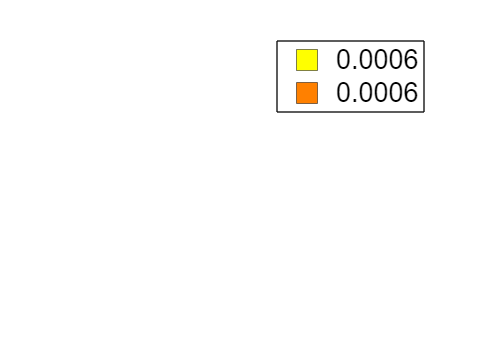

Extracting image data for significant clusters. Extracting data for multilevel mediation
 001 002 003 004 005 006 007 008 009 010 011 012 013 014 015 016 017 018 019 020 021 022 023 024 025 026 027 028 029 030 031 032 033 034 035 036 037 038 039 040 041 042 043 044 045 046 047 048 049 050 051 052 053 054 055 056 057 058 059 060 061 062 063 064 065 066

Extracting image data for significant clusters. Extracting data for multilevel mediation
 001 002 003 004 005 006 007 008 009 010 011 012 013 014 015 016 017 018 019 020 021 022 023 024 025 026 027 028 029 030 031 032 033 034 035 036 037 038 039 040 041 042 043 044 045 046 047 048 049 050 051 052 053 054 055 056 057 058 059 060 061 062 063 064 065 066



Summary of output images:
X-M_pvals.img
Results clusters clpos and clneg are returned for the LAST image in this set.
 
Printing Tables.
 
Z field contains: Mediation a effect (shown in maxstat)
 
Name	index	x	y	z	corr	voxels	volume_mm3	maxstat	snr_avgts(d)	minsnr	maxsnr	numpos	power80	partialr_with_y	partialr_p	Za_max	Pa_max	Zb_max	Pb_max	Zab_max	Pab_max	num_sig_voxels	
Cblm_VIIIb_R	  1	 22	-40	-52	NaN	  7	 56	12.36	0.31	0.12	0.45	 23	165	NaN	NaN	4.60	0.0000	-0.2334	0.82	1.70	0.09	
Cblm_CrusII_R	  2	 44	-60	-48	NaN	  8	 64	9.68	0.22	0.09	0.29	 25	333	NaN	NaN	4.00	0.0001	-0.2684	0.79	-0.0793	0.94	
Cblm_CrusII_L	  3	-44	-48	-44	NaN	 13	104	10.87	0.09	-0.01	0.15	 16	1806	NaN	NaN	4.28	0.0000	-0.5042	0.61	-0.4797	0.63	
Cblm_CrusII_R	  4	 46	-50	-46	NaN	  9	 72	22.37	-0.03	-0.11	0.11	 24	14895	NaN	NaN	6.37	0.0000	-1.6950	0.09	-0.3727	0.71	
Cblm_X_R	  5	 20	-30	-44	NaN	  6	 48	17.42	NaN	NaN	NaN	  0	NaN	NaN	NaN	5.56	0.0000	-0.4897	0.62	-0.2150	0.83	
Cblm_CrusI_L	  6	-50	-54	-36	NaN	  6	 48	10

Will show slices.
Will print tables.
Saving log file: M-Y_pvals_0006_k5_noprune_log.txt
Other key results in: M-Y_pvals_0006_k5_noprune_results.txt
Will also save figures of slice montages if 'slices' requested.

iimg_multi_threshold viewer
Showing positive or negative: pos
Overlay is: D:\Tools\MATLAB2022b\toolbox\CanlabCore\CanlabCore\canlab_canonical_brains\Canonical_brains_surfaces\SPM8_colin27T1_seg.img
No mask specified in iimg_multi_threshold
Entered p-value image? : Yes
Height thresholds:0.0006 
Extent thresholds:   5 
Show only contiguous with seed regions: No
 
log(1/p) saved in output cl.Z field.

SPM12: spm_check_registration (v7759)              03:35:48 - 21/08/2026
Display 

Extracting image data for significant clusters. Extracting data for multilevel mediation
 001 002 003 004 005 006 007 008 009 010 011 012 013 014 015 016 017 018 019 020 021 022 023 024 025 026 027 028 029 030 031 032 033 034 035 036 037 038 039 040 041 042 043 044 045 046 047 048 049 050 051 052 053 054 055 056 057 058 059 060 061 062 063 064 065 066

Extracting image data for significant clusters. Extracting data for multilevel mediation
 001 002 003 004 005 006 007 008 009 010 011 012 013 014 015 016 017 018 019 020 021 022 023 024 025 026 027 028 029 030 031 032 033 034 035 036 037 038 039 040 041 042 043 044 045 046 047 048 049 050 051 052 053 054 055 056 057 058 059 060 061 062 063 064 065 066



Summary of output images:
M-Y_pvals.img
Results clusters clpos and clneg are returned for the LAST image in this set.
 
Printing Tables.
 
Z field contains: Mediation b effect (shown in maxstat)
 
Name	index	x	y	z	corr	voxels	volume_mm3	maxstat	snr_avgts(d)	minsnr	maxsnr	numpos	power80	partialr_with_y	partialr_p	Za_max	Pa_max	Zb_max	Pb_max	Zab_max	Pab_max	num_sig_voxels	
Cblm_VIIIb_L	  1	-12	-46	-64	NaN	  5	 40	12.18	0.28	0.28	0.28	 23	210	NaN	NaN	0.74	0.46	4.56	0.0000	-0.8401	0.40	
Cblm_VIIb_L	  2	-30	-62	-50	NaN	  5	 40	7.87	0.14	-0.08	0.33	 20	879	NaN	NaN	0.35	0.72	3.55	0.0004	-0.4232	0.67	
Cblm_CrusII_L	  3	 -2	-84	-42	NaN	 13	104	19.00	NaN	NaN	NaN	  0	NaN	NaN	NaN	-2.3974	0.02	5.83	0.0000	-1.0735	0.28	
Ctx_PeEc_R	  4	 34	-14	-40	NaN	  8	 64	15.07	-0.09	-0.09	-0.09	 20	1848	NaN	NaN	0.76	0.45	5.13	0.0000	0.48	0.63	
Ctx_PeEc_L	  5	-24	 -2	-42	NaN	  5	 40	11.53	NaN	NaN	NaN	  0	NaN	NaN	NaN	-1.5013	0.13	4.42	0.0000	-1.2252	0.22	
Ctx_TGd_R	  6	 38	 20	-44	NaN	  8	 64	24.94	-0.09	-0.22	0.0

Will show slices.
Will print tables.
Saving log file: X-M-Y_pvals_0006_k5_noprune_log.txt
Other key results in: X-M-Y_pvals_0006_k5_noprune_results.txt
Will also save figures of slice montages if 'slices' requested.

iimg_multi_threshold viewer
Showing positive or negative: pos
Overlay is: D:\Tools\MATLAB2022b\toolbox\CanlabCore\CanlabCore\canlab_canonical_brains\Canonical_brains_surfaces\SPM8_colin27T1_seg.img
No mask specified in iimg_multi_threshold
Entered p-value image? : Yes
Height thresholds:0.0006 
Extent thresholds:   5 
Show only contiguous with seed regions: No
 
log(1/p) saved in output cl.Z field.

SPM12: spm_check_registration (v7759)              03:36:30 - 21/08/2026
Display 

Extracting image data for significant clusters. Extracting data for multilevel mediation
 001 002 003 004 005 006 007 008 009 010 011 012 013 014 015 016 017 018 019 020 021 022 023 024 025 026 027 028 029 030 031 032 033 034 035 036 037 038 039 040 041 042 043 044 045 046 047 048 049 050 051 052 053 054 055 056 057 058 059 060 061 062 063 064 065 066

Extracting image data for significant clusters. Extracting data for multilevel mediation
 001 002 003 004 005 006 007 008 009 010 011 012 013 014 015 016 017 018 019 020 021 022 023 024 025 026 027 028 029 030 031 032 033 034 035 036 037 038 039 040 041 042 043 044 045 046 047 048 049 050 051 052 053 054 055 056 057 058 059 060 061 062 063 064 065 066



Summary of output images:
X-M-Y_pvals.img
Results clusters clpos and clneg are returned for the LAST image in this set.
 
Printing Tables.
 
Z field contains: Mediation ab effect (shown in maxstat)
 
Name	index	x	y	z	corr	voxels	volume_mm3	maxstat	snr_avgts(d)	minsnr	maxsnr	numpos	power80	partialr_with_y	partialr_p	Za_max	Pa_max	Zb_max	Pb_max	Zab_max	Pab_max	num_sig_voxels	
Cblm_CrusII_R	  1	 18	-88	-46	NaN	  5	 40	8.55	NaN	NaN	NaN	  0	NaN	NaN	NaN	-0.7026	0.48	-0.3791	0.70	3.73	0.0002	
Cblm_CrusI_R	  2	 46	-44	-36	NaN	  5	 40	12.00	NaN	NaN	NaN	  0	NaN	NaN	NaN	0.99	0.32	-0.4325	0.67	4.52	0.0000	
Cblm_VI_R	  3	 34	-46	-24	NaN	  7	 56	8.84	0.58	0.29	0.66	 26	 49	NaN	NaN	1.36	0.18	-0.4215	0.67	3.80	0.0001	
No label	  4	-54	-72	-16	NaN	  5	 40	13.55	NaN	NaN	NaN	  0	NaN	NaN	NaN	0.50	0.62	0.20	0.84	4.84	0.0000	
Bstem_Ponscd	  5	-26	-12	 -8	NaN	  5	 40	9.37	-0.25	-0.36	-0.06	 16	266	NaN	NaN	-0.9202	0.36	1.93	0.05	3.93	0.0001	
No label	  6	-42	-56	  4	NaN	  8	 64	8.86	-0.21	-0.34	-0.03	 16	373	

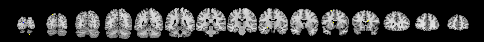

Saving image of slices: orth_X-M-Y_pvals_0006_k5_noprune_sagittal.png


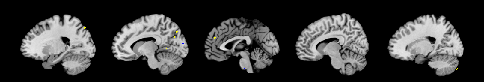

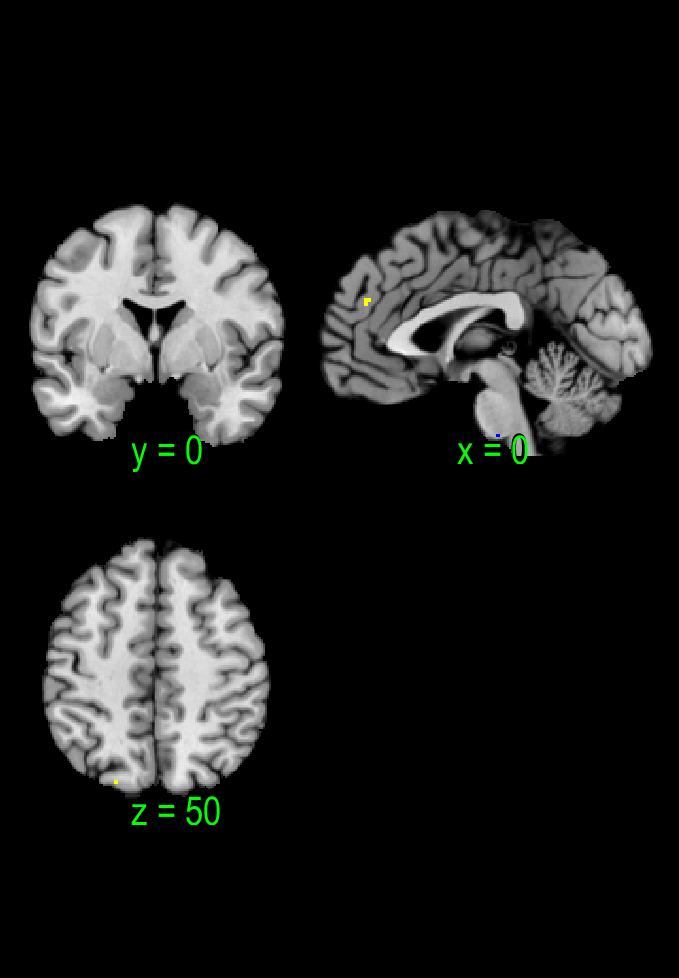

Saving image of slices: orth_X-M-Y_pvals_0006_k5_noprune_axial.png


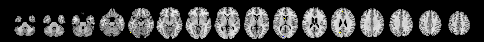

Completed analysis: No Moderator


Search for mediators
First-level covariates:  None
Second-level moderators:    1 Found: Creating additional L2mod output images.
Found mask: D:/Research/MS_Thesis/Study2/Output/Image/masks/group_mask_belief_run01.nii
Preparing data.
Mask info:
Dimensions:  77  95  82
Voxels in mask: 251715
Mapping all input data volumes to memory
Subject   1,   1 images.
Subject   2,   1 images.
Subject   3,   1 images.
Subject   4,   1 images.
Subject   5,   1 images.
Subject   6,   1 images.
Subject   7,   1 images.
Subject   8,   1 images.
Subject   9,   1 images.
Subject  10,   1 images.
Subject  11,   1 images.
Subject  12,   1 images.
Subject  13,   1 images.
Subject  14,   1 images.
Subject  15,   1 images.
Subject  16,   1 images.
Subject  17,   1 images.
Subject  18,   1 images.
Subject  19,   1 images.
Subject  20,   1 images.
Subject  21,   1 images.
Subject  22,   1 images.
Subject  23,   1 images.
Subject  24,   1 images.
Subject  25,   1 images.
Subject  26,   1 images.
Subject  27,   1 i

  0%Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need

  1%Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need

  2%Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need

  3%Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
Additions 10/28/19 by Tor Wager to add output to within-ss stats need


analyses = {
    'nomod',  [],         'No Moderator';
    'Group',  Group_vec,  'Moderator: Group';
    'NPS',    NPS_vec,    'Moderator: centered NPS';
};

SETUP.mask           = group_mask;
SETUP.preprocX       = 0;
SETUP.preprocY       = 0;
SETUP.preprocM       = 0;
SETUP.wh_is_mediator = 'M';

for a = 1:size(analyses, 1)
    mod_name  = analyses{a, 1};
    L2M_cur   = analyses{a, 2};
    mod_label = analyses{a, 3};

    result_subdir = fullfile(OUTPUT_DIR, mod_name);
    if ~exist(result_subdir, 'dir'), mkdir(result_subdir); end
    cd(result_subdir);

    if isempty(L2M_cur)
        mediation_brain_multilevel(X, Y, M, SETUP, ...
            'nopreproc', ...
            'names', {'EE', 'Update', 'BOLD'}, ...
            'boot', 'bootsamples', 2000, 'doplots', 'dosave');
    else
        mediation_brain_multilevel(X, Y, M, SETUP, ...
            'nopreproc', 'L2M', L2M_cur, ...
            'names', {'EE', 'Update', 'BOLD'}, ...
            'boot', 'bootsamples', 2000, 'doplots', 'dosave');
    end

    SETUP_cur = mediation_brain_corrected_threshold('fdr');

    mediation_brain_results('a', 'thresh', SETUP_cur.fdr_p_thresh, 'size', 5, 'slices', 'tables', 'names', 'save');
    mediation_brain_results('b',  'thresh', SETUP_cur.fdr_p_thresh, 'size', 5, 'slices', 'tables', 'names', 'save');
    mediation_brain_results('ab', 'thresh', SETUP_cur.fdr_p_thresh, 'size', 5, 'slices', 'tables', 'names', 'save');
    fprintf('Completed analysis: %s\n', mod_label);
end